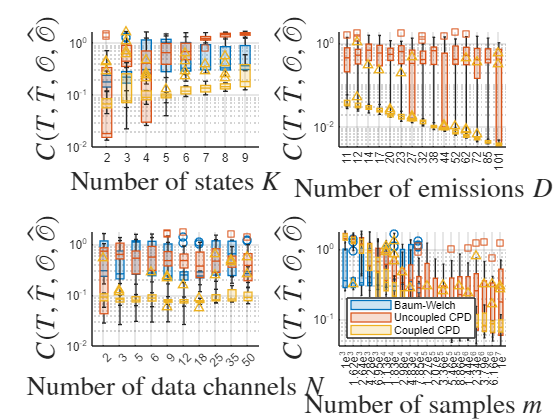

load("PerformanceTests/PerformanceOverStates")


figure()
cmap = orderedcolors("gem");


subplot(2, 2, 1)

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(Krange);
set(gca,'YScale','log');
grid on;
ylabel("$C(T, \hat{T}, \mathcal{O}, \hat{\mathcal{O}})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

load("PerformanceTests/PerformanceOverEmissions")

subplot(2, 2, 2)

boxchart(zeros(size(Drange,2), 1), "MarkerStyle", 's'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(Drange);
set(gca,'YScale','log');

grid on;
ylabel("$C(T, \hat{T}, \mathcal{O}, \hat{\mathcal{O}})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of emissions $D$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% legend("Uncoupled CPD", "Coupled CPD", Location="southwest");
hold off;


subplot(2,2,3)
load("PerformanceTests/PerformanceOverSequences")
% boxplot(BWCost', Nrange, 'Symbol', 'o', Colors=cmap(1, :)); hold on;
% boxplot(UncoupledCost', Nrange, 'Symbol', 's', Colors=cmap(2, :)); hold on;
% boxplot(CoupledCost', Nrange, 'Symbol', '^', Colors=cmap(3, :)); hold on;

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(Nrange);

set(gca,'YScale','log');

grid on;
ylabel("$C(T, \hat{T}, \mathcal{O}, \hat{\mathcal{O}})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of data channels $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold');
hold off;



load("PerformanceTests/Time_Performance_Costs2");


subplot(2, 2, 4)

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

set(gca,'YScale','log');
grid on;

ax = gca;

mantissa = sampleArray ./ 10.^floor(log10(sampleArray));
exponent = floor(log10(sampleArray));

labels = arrayfun(@(m,e) sprintf('%.3ge^%d', m, e), ...
                  mantissa, exponent, ...
                  'UniformOutput', false);

ax.XAxis.TickLabels = labels;

ylabel("$C(T, \hat{T}, \mathcal{O}, \hat{\mathcal{O}})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", Location="southwest");
hold off;

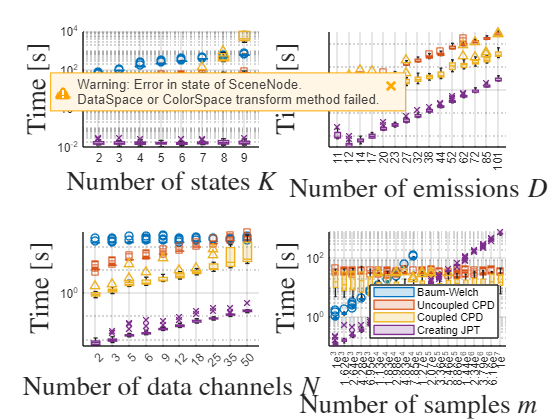



figure()

subplot(2, 2, 1)
load("PerformanceTests/PerformanceOverStates")

boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(Krange);

set(gca,'YScale','log');
grid on; 
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')



subplot(2, 2, 2)
load("PerformanceTests/PerformanceOverEmissions")
boxchart(zeros(size(Drange,2), 1), "MarkerStyle", 's'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(Drange);

set(gca,'YScale','log');
grid on; 
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of emissions $D$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% legend("Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");


subplot(2, 2, 3)
load("PerformanceTests/PerformanceOverSequences")

% boxplot(BWTime', Nrange, 'Symbol', 'o', Colors=cmap(1, :)); hold on;
% boxplot(UncoupledTime', Nrange, 'Symbol', 's', Colors=cmap(2, :)); hold on;
% boxplot(CoupledTime', Nrange, 'Symbol', '^', Colors=cmap(3, :)); hold on;
% boxplot(JPTTime', Nrange, 'Symbol', 'x', Colors=cmap(4, :)); hold on;

boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(Nrange);

set(gca,'YScale','log');
grid on; 
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of data channels $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')


load("PerformanceTests/Time_Performance_Costs2");

subplot(2, 2, 4)
boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
set(gca,'YScale','log')
grid on


ax = gca;

mantissa = sampleArray ./ 10.^floor(log10(sampleArray));
exponent = floor(log10(sampleArray));

labels = arrayfun(@(m,e) sprintf('%.3ge^%d', m, e), ...
                  mantissa, exponent, ...
                  'UniformOutput', false);

ax.XAxis.TickLabels = labels;



legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')